# Post Process Radar Data

Script Summary

- Read key information on the MMWave Device

- Generate an ADC Data Cube sorted by (frame,chirp, rx channel, sample)

- Plot ADC data as desired

- Compute Range FFT

- Generate 2D FFT and display a range-doppler plot 

Assumptions:

- Using IWR1443 Radar

## Read mmWave Device Information

Start by declaring the location of the adc_data.bin, mmwave.json, and setup.json files are located. If the location is known, put them into the script, otherwise, there are helper functions to get the files as needed

clear;
%if the file locations are known, list them here

% %for ubuntu
% data_path = "/home/david/Documents/mmWave_data/AoA testing_mar_1_2023";
% adc_data_file_name = strcat(data_path,"/adc_data.bin");
% mmwave_setup_json_file_name = strcat(data_path,"/config/mmWave_config.mmwave.json");


%otherwise use these helper functions
mmwave_json_file_name = GET_MMWAVE_SETUP_JSON_FILE();

User selected C:\Users\david\Documents\GitHub\mmWaveStudioProcessing\sample_configurations\indoor_walking.mmwave.json 


adc_bin_file_name = GET_ADC_DATA_BIN_FILE();

User selected C:\Users\david\Documents\GitHub\mmWaveStudioProcessing\sample_datasets\adc_data.bin 


Next, instantiate a MMWaveDeviceClass which reads the mmwave.setup file to obtain all necessary information from the mmWave Device

mmWave_device = MMWaveDevice(adc_bin_file_name,mmwave_json_file_name);
mmWave_device.printDeviceConfiguration();

# of sample/chirp: 256
# of chirp/frame: 255
# of sample/frame: 261120
Size of one frame: 1044480 Bytes
# of frames in the raw ADC data file: 300

Rx channels enabled: [1,1,1,1]
#of Rx channels: 4

Radar bandwidth: 3.82 (GHz)

ADC sampling rate: 2.81 (MSa/s)
ADC bits: 16 bit
dBFS scaling factor: -129.48 (dB)

Chirp duration: 104.00 (usec)
Chirp slope: 42.00 (MHz/usec)
Chirp bandwidth: 3823.89 (MHz)
Chirp "valid" duration: 91.04 (usec)

Frame length: 26.52 (msec)
Frame periodicity: 30.00 (msec)
Frame duty-cycle: 0.88 

Range limit: 10.0352 (m)
Range resolution: 0.0392 (m)
Velocity limit: 9.3592 (m/s)
Velocity resolution: 0.0734 (m/s)

IQ swap?: 0
Interleaved data?: 0
...System configuration imported!



## Generate ADC Data Cube

First, use the helper function to read the adc_data.bin file and sort the data into a continuous stream of samples for each LVDS lane (each Rx Channel)

raw_adc_data = READ_ADC_DATA_BIN_FILE(adc_bin_file_name,mmWave_device);

Next we generate the adc_data_cube which will be indexed as follows:

- adc_data_cube[rx channel, sample, chirp, frame]

num_frames = mmWave_device.num_frame;
chirps_per_frame = mmWave_device.num_chirp_per_frame;
rx_channels = mmWave_device.num_rx_chnl;
samples_per_chirp = mmWave_device.num_sample_per_chirp;


%generate an adc_data_cube
adc_data_cube = reshape(raw_adc_data,rx_channels,samples_per_chirp,chirps_per_frame,num_frames);

%print data from 1st chirp of 1st frame
adc_data_cube(:,:,1,1);
%print shape of the adc_data_cube
size(adc_data_cube)

ans =      4   256   255   300


### Plot a desired Frame and Chirp

Code to setup the plot

sampling_period = 1/mmWave_device.adc_samp_rate;
t = 0:sampling_period:sampling_period*samples_per_chirp - sampling_period;

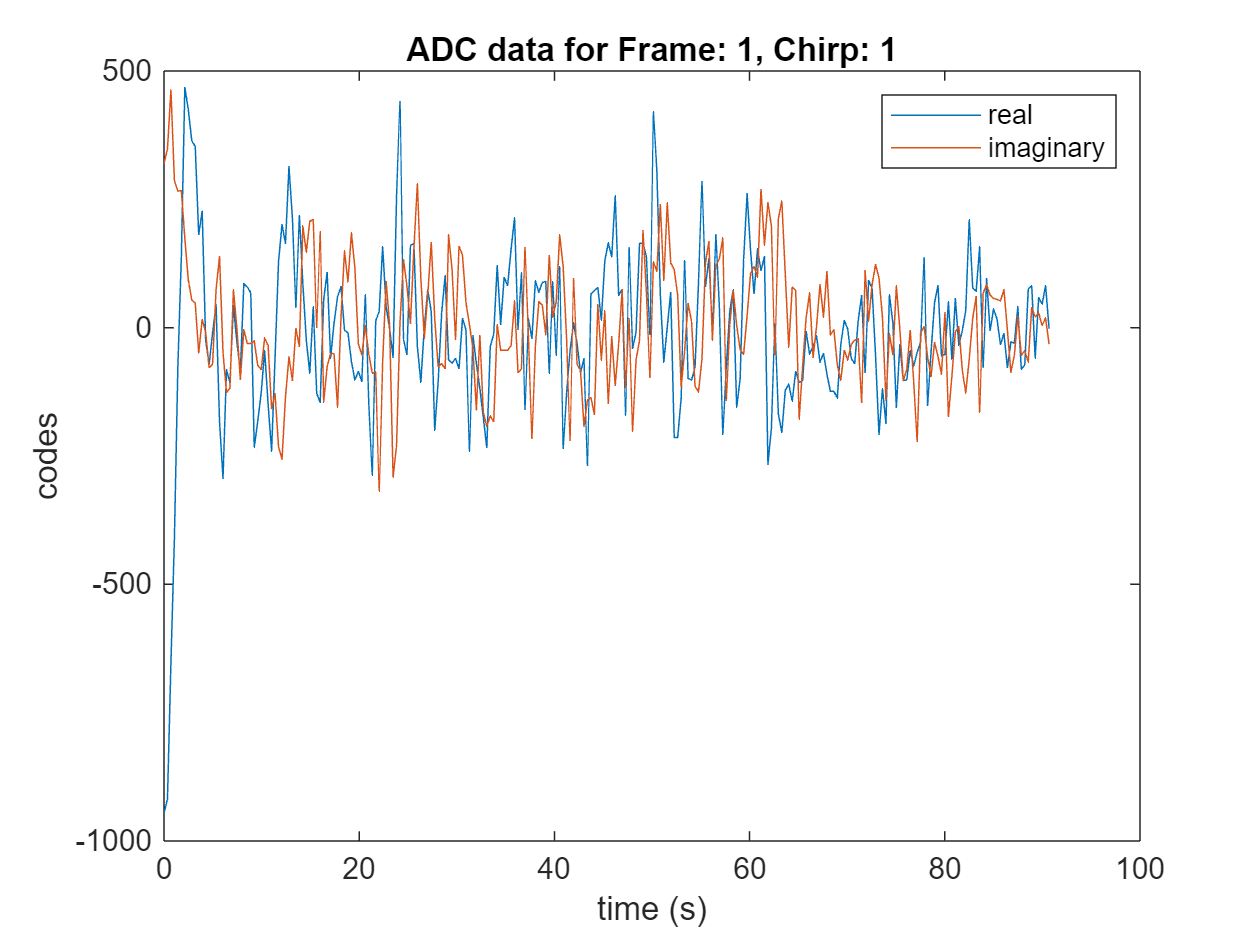

clf;
%Desired Frame
desired_frame = 1;
%Desired Chirp
desired_chirp = 1;
%Desired Rx Channel - Hardcoded to channel 1 for now
rx_channel = 1;
data = adc_data_cube(rx_channel,:,desired_chirp,desired_frame);
real_data = real(data);
imaginary_data = imag(data);
plot(t,real_data,t,imaginary_data)
xlabel('time (s)');
ylabel('codes');
% ylim([-500,500])
title_str = sprintf('ADC data for Frame: %d, Chirp: %d',desired_frame, desired_chirp);
title(title_str);
legend('real','imaginary');

## Range FFT

### Calculate and plot range FFT for a single chirp

ranges = (0:mmWave_device.num_sample_per_chirp - 1) * mmWave_device.range_res;

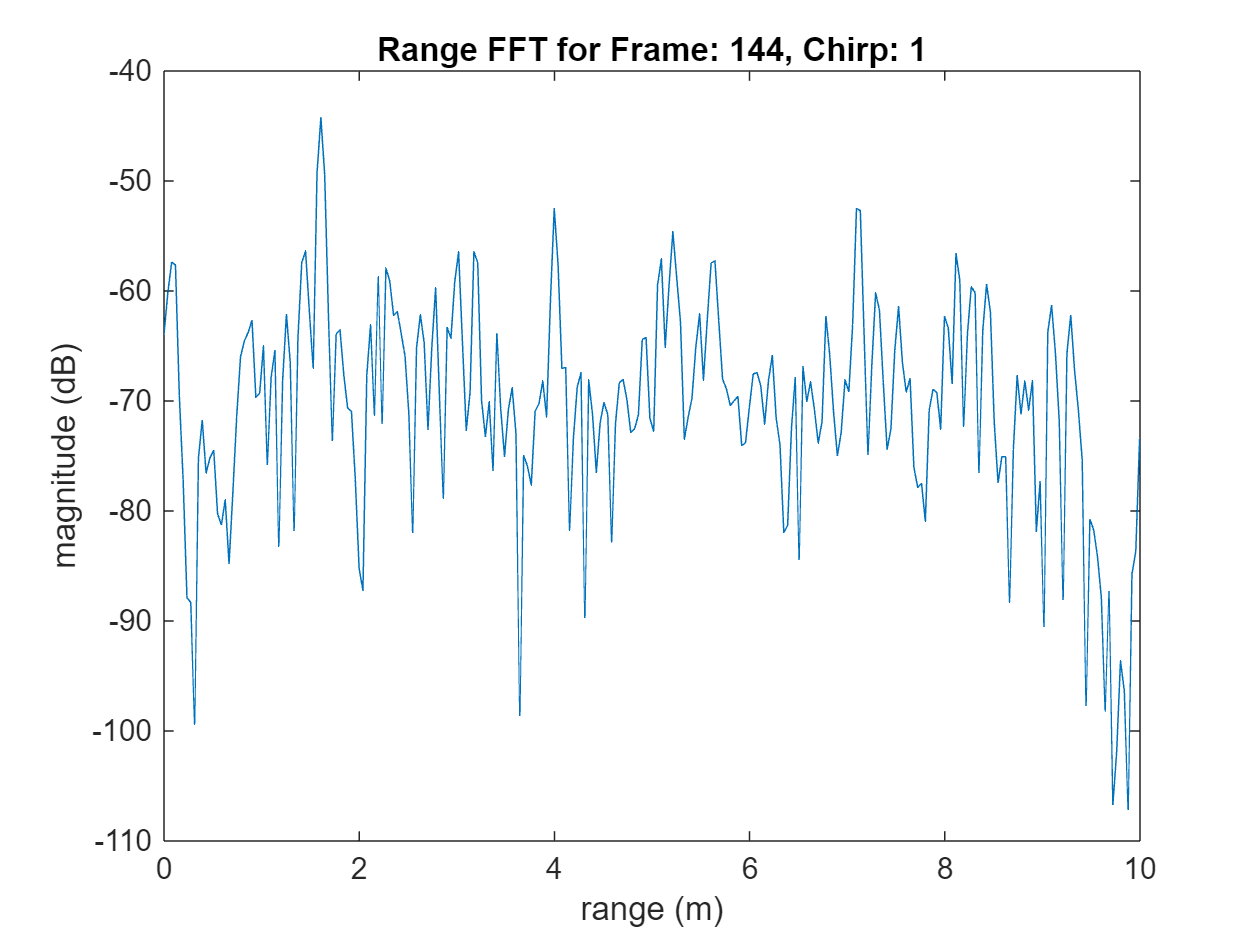

clf;
%Desired Frame
desired_frame = 144;
%Desired Chirp
desired_chirp = 1;
%Desired Rx Channel - Hardcoded to channel 1 for now
rx_channel = 1;

fft_ = 20 * log10(abs(fft( ...
    mmWave_device.win_hann.' .* ...
    adc_data_cube(rx_channel,:,desired_chirp,desired_frame)))); 
plot(ranges,abs(fft_) + mmWave_device.dbfs_coeff); %apply the dbfs coeff when performing the offset
xlabel('range (m)')
ylabel('magnitude (dB)')
title_str = sprintf('Range FFT for Frame: %d, Chirp: %d',desired_frame, desired_chirp);
title(title_str);

### Plot Range FFT next to ADC Plot for a desired Chirp and Frame

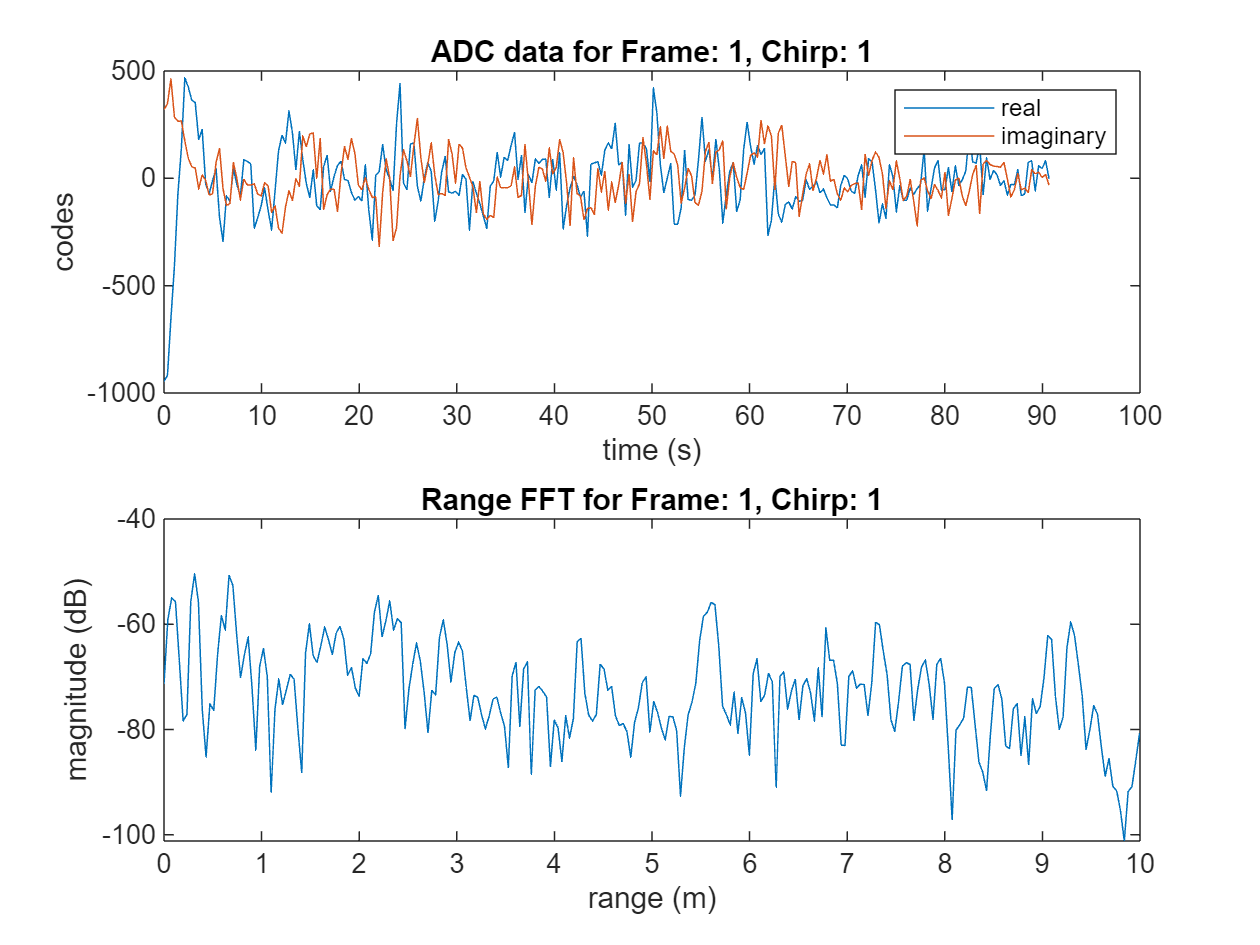

clf;
%Desired Frame
desired_frame = 1;
%Desired Chirp
desired_chirp = 1;
%Desired Rx Channel - Hardcoded to channel 1 for now
rx_channel = 1;



%adc data calculation
data = adc_data_cube(rx_channel,:,desired_chirp,desired_frame);
real_data = real(data);
imaginary_data = imag(data);
subplot(2,1,1)
plot(t,real_data,t,imaginary_data)
xlabel('time (s)');
ylabel('codes');
title_str = sprintf('ADC data for Frame: %d, Chirp: %d',desired_frame, desired_chirp);
title(title_str);
legend('real','imaginary');

%fft calculation
fft_ = 20 * log10(abs(fft( ...
    mmWave_device.win_hann.' .* ...
    adc_data_cube(rx_channel,:,desired_chirp,desired_frame)))); subplot(2,1,2);
plot(ranges,abs(fft_) + mmWave_device.dbfs_coeff); %apply the dbfs coeff when performing the offset
xlabel('range (m)')
ylabel('magnitude (dB)')
title_str = sprintf('Range FFT for Frame: %d, Chirp: %d',desired_frame, desired_chirp);
title(title_str);

### Generate 2D- FFT Plot

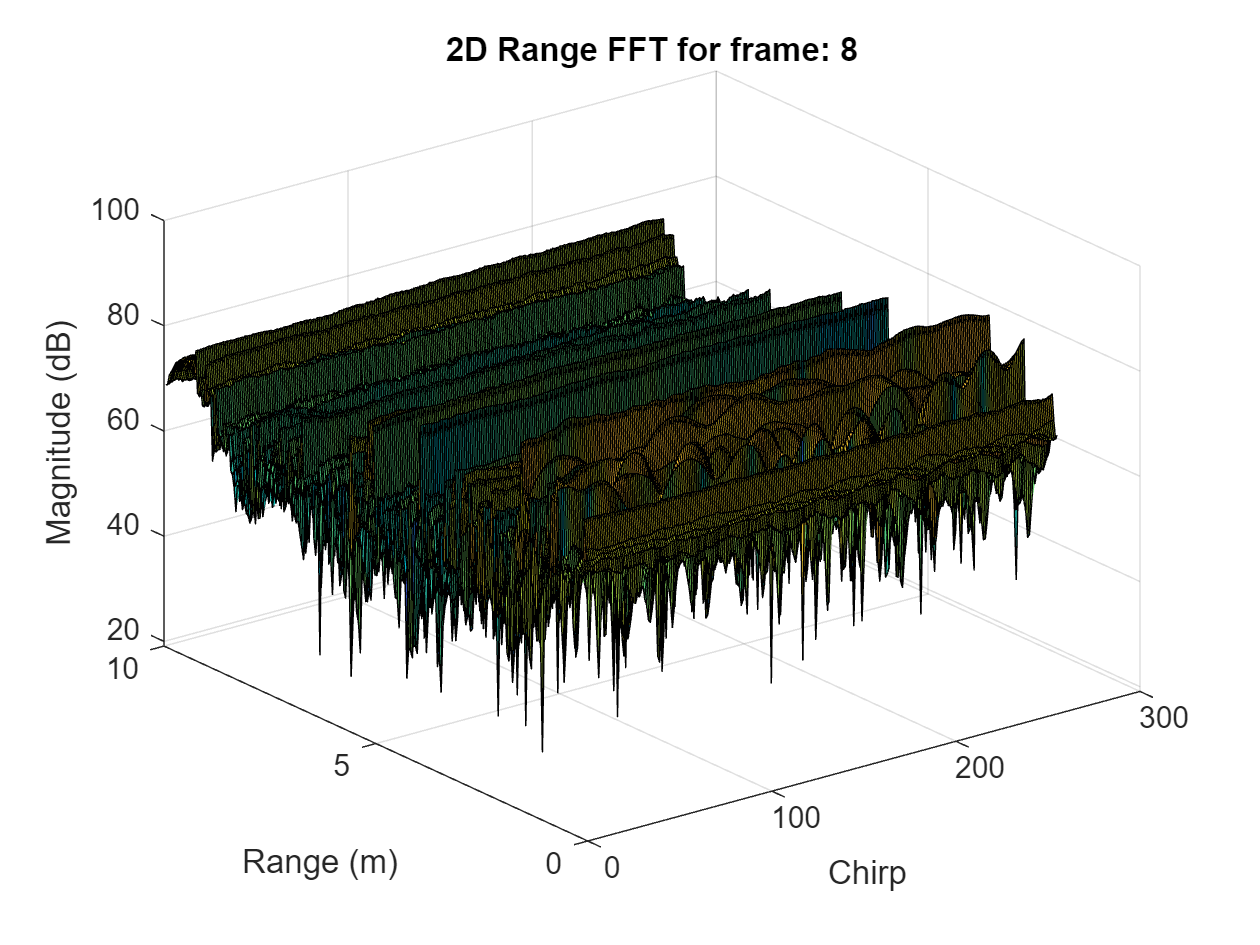

clf;
%Desired Frame
desired_frame = 8;
rx_channel = 1;

frame_data = adc_data_cube(rx_channel,:,:,desired_frame);
frame_data = reshape(frame_data,samples_per_chirp,chirps_per_frame);

fft_2d_range = 20 * log10(abs(fft(frame_data)));
x_vals = 1:chirps_per_frame;
surf(x_vals, ranges, fft_2d_range);
title_str = sprintf('2D Range FFT for frame: %d',desired_frame);
title(title_str);
xlabel('Chirp')
ylabel('Range (m)')
zlabel('Magnitude (dB)')

adc_channel_data_cube = reshape(adc_data_cube(rx_channel,:,:,:),samples_per_chirp,chirps_per_frame,num_frames);
fft_2d_range_cube = zeros(samples_per_chirp,chirps_per_frame,num_frames);

for frame_index = 1:num_frames
    fft_2d_range_cube(:,:,frame_index) = fft(adc_channel_data_cube(:,:,frame_index));
end


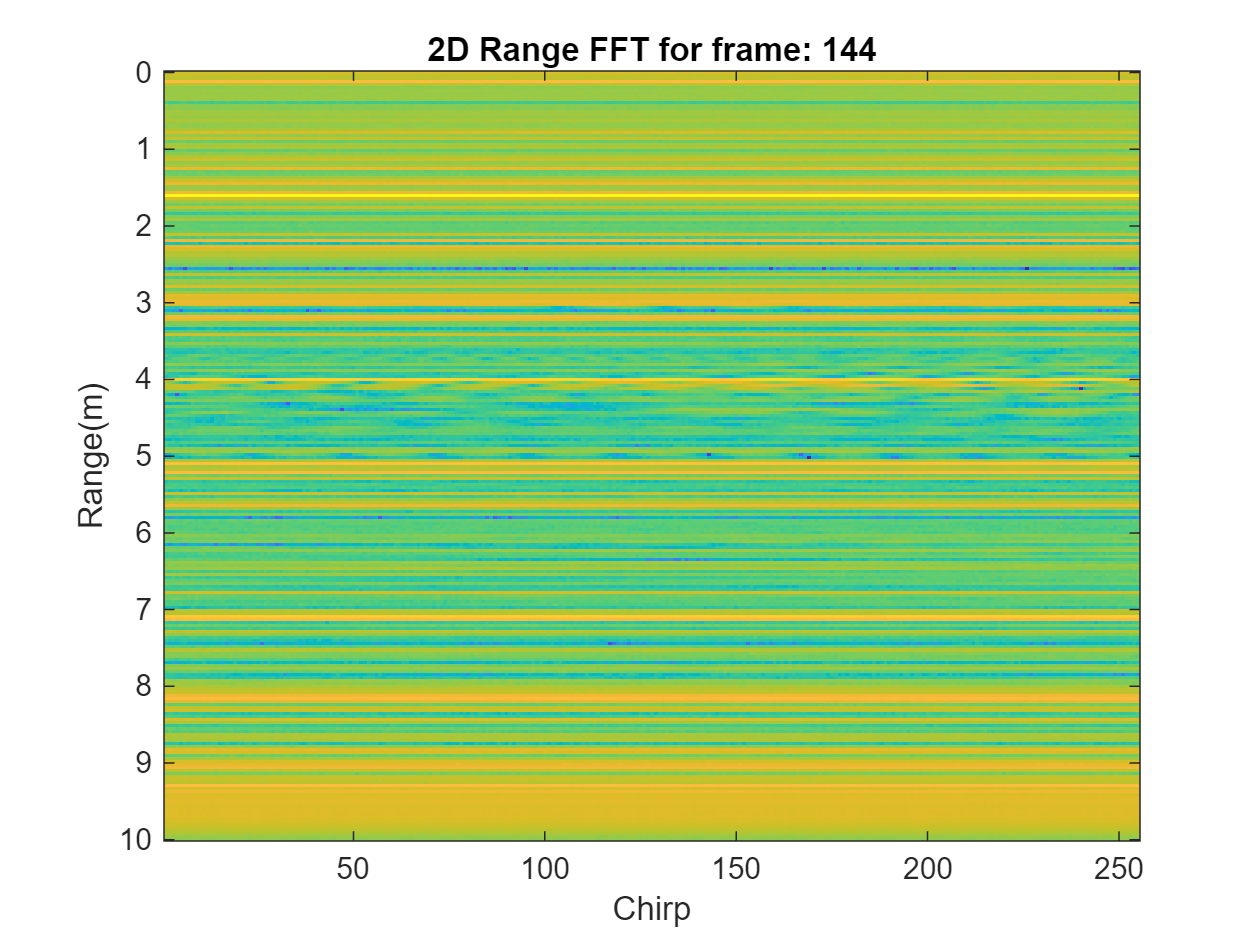


clf;
%Desired Frame
desired_frame = 144;


frame_data = 20*log10(abs(fft_2d_range_cube(:,:,desired_frame)));
x_vals = 1:chirps_per_frame;
%surf(x_vals,ranges, frame_data);
imagesc(x_vals,ranges, frame_data);
title_str = sprintf('2D Range FFT for frame: %d',desired_frame);
title(title_str);
xlabel('Chirp')
ylabel('Range(m)')
zlabel('Magnitude (dB)')

## Range-Doppler FFT

rx_channel = 1;
%adc_channel_data_cube = reshape(adc_data_cube(rx_channel,:,:,:),samples_per_chirp,chirps_per_frame,num_frames);
%fft_2d_range_cube = zeros(samples_per_chirp,chirps_per_frame,num_frames);

fft_range_doppler_cube = zeros(samples_per_chirp,chirps_per_frame,num_frames);

for frame_index = 1:num_frames
    fft_range_doppler_cube(:,:,frame_index) = fftshift(fft(fft_2d_range_cube(:,:,frame_index).').',2);
end

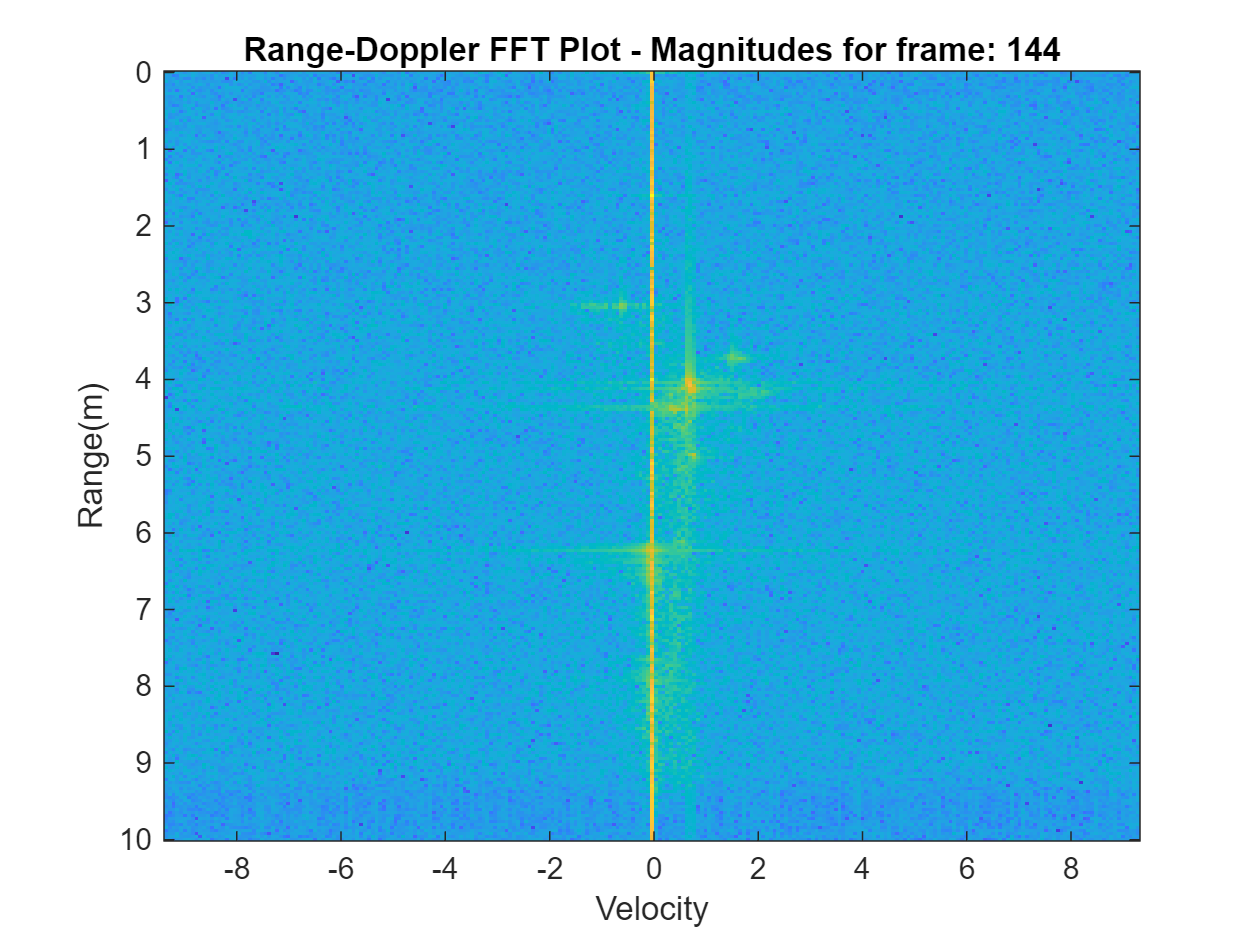

clf;
%Desired Frame
desired_frame = 144;


frame_data = 20*log10(abs(fft_range_doppler_cube(:,:,desired_frame)));
v_max = mmWave_device.v_max;
v_res = mmWave_device.v_res;
velocities = -v_max:v_res:(v_max-v_res);

% subplot(2,1,1)
% surf(velocities,ranges, frame_data);
% title('Range-Doppler FFT Plot - As Surf')
% xlabel('Velocity')
% ylabel('Range(m)')
% zlabel('Magnitude (dB)')

% subplot(2,1,2)
imagesc(velocities,ranges, frame_data);
title_str = sprintf('Range-Doppler FFT Plot - Magnitudes for frame: %d',desired_frame);
title(title_str);
xlabel('Velocity')
ylabel('Range(m)')

## Generate Range-Azimuth plot using fft

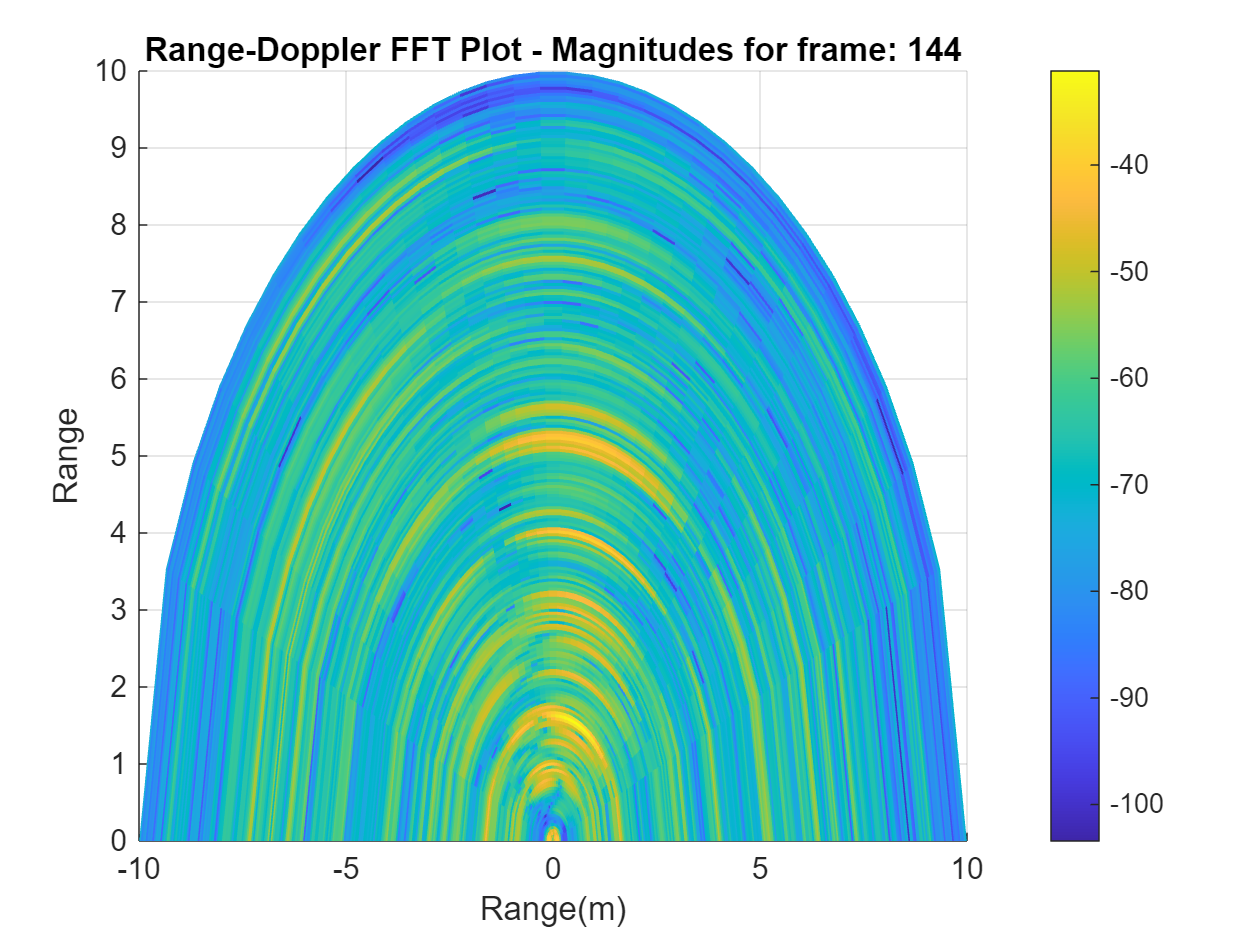

%obtain the data for all 4 channels at a specific chirp and frame index
desired_frame = 8;
desired_chirp = 1;

%determine the angular coordinates and the associated AoA
num_angle_bins = 32;
angles = (-1 * pi:2 * pi/(num_angle_bins - 1):pi) * -1;
AoA_coordinates_rad = asin(angles/pi);

%define the amount of zero padding to add
range_angle_cube = zeros(mmWave_device.num_sample_per_chirp,num_angle_bins);

%obtain the frame data
frame_data = adc_data_cube(:,:,desired_chirp,desired_frame).';
range_angle_cube(:,1:mmWave_device.num_rx_chnl) = fft(mmWave_device.win_hann .* frame_data);
range_angle_cube = fftshift(fft(range_angle_cube,num_angle_bins,2),2);
% 
% frame_data = 20*log10(abs(fft_2d_range_cube(:,:,desired_frame)));
x_vals = AoA_coordinates_rad;
% imagesc(x_vals,ranges, 20 * log10(abs(range_angle_cube)));
[thetas,rhos] = meshgrid(AoA_coordinates_rad,ranges);
[X,Y] = pol2cart(thetas,rhos);
surf(X,Y, 20 * log10(abs(range_angle_cube)) + mmWave_device.dbfs_coeff,'EdgeColor','none');
view(90,270)
%title_str = sprintf('2D Range FFT for frame: %d',desired_frame);
title(title_str);
xlabel('Range')
ylabel('Range(m)')
zlabel('Magnitude (dB)')
colorbar;

## Generating Microdopler Signatures

In the future I will use matlab's findpeaks() function to get the exact "range" of the peak

%get the range fft from the 1st chirp of the desired frame
desired_frame = 1;
desired_chirp = 1;
peak_threshold = 70;
frame_data = 20*log10(abs(fft_2d_range_cube(:,desired_chirp,desired_frame)));
[peaks,locations] = findpeaks(frame_data,...
                            "MinPeakHeight",peak_threshold);
%connect the peak location with a range
peak_index = locations;
peak_ranges = ranges(peak_index)

peak_ranges =     0.1176    0.3136    0.6664    0.8232    0.9800    1.1760    1.3328    1.4896    1.6464    1.7640    1.8424    1.9208    2.1168    2.1952    2.3128    2.4304    2.8616    4.2336    5.5272    5.6448    6.7816    6.8600    7.2912    8.9768    9.0552    9.2120    9.2904    9.3688    9.5256    9.6040



%filter the results to only ones where there could have been a gesture
potential_peak_ranges = peak_ranges(and(peak_ranges < 1.0, peak_ranges > 0.6))

potential_peak_ranges =     0.6664    0.8232    0.9800


peak_index_guess = find(ranges == potential_peak_ranges(1))

peak_index_guess = 18

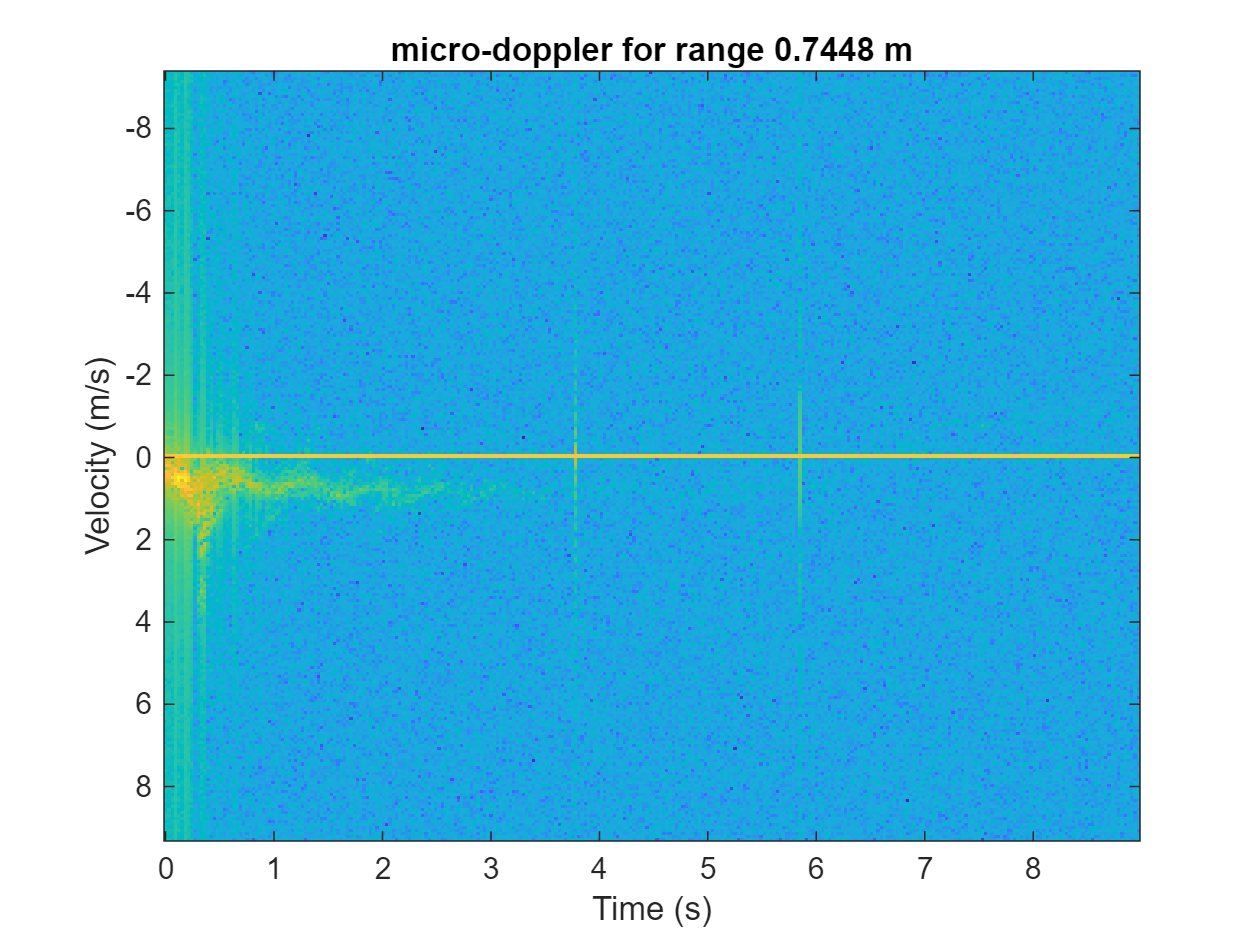

clf;

peak_index = 20;

%next, get the micro-doppler signature from every frame at the specified
%distance
micro_doppler_at_range = reshape(20*log10(abs(fft_range_doppler_cube(peak_index,:,:))),chirps_per_frame,num_frames);

%finally generate a plot:
v_max = mmWave_device.v_max;
v_res = mmWave_device.v_res;
velocities = -v_max:v_res:(v_max-v_res);

frame_periodicity = mmWave_device.frame_periodicity * 1e-3;
times = 0:frame_periodicity:num_frames*frame_periodicity - frame_periodicity;

plot_title = sprintf('micro-doppler for range %0.4f m',ranges(peak_index));

imagesc(times,velocities, micro_doppler_at_range);
title(plot_title)
xlabel('Time (s)')
ylabel('Velocity (m/s)')

% 
% surf(times,velocities, micro_doppler_at_range);
% title(plot_title)
% xlabel('Velocity')
% ylabel('Range(m)')
% zlabel('Magnitude (dB)')